# Final Exam

# Course 2023-24 Q1

## **Problem 4**

Consider the heat equation $-\Delta T = 0$ on the domain $D$ meshed in the file `meshDataHoleS5.m` (see Figure 1). Let us define the **interior boundary** $C$, as the small circumference inside the domain and the **exterior boundary** $E$ as the remaining part of the boundary of $D$ (i.e., $E = \partial\Omega\setminus C$). We also consider $L$, the left part of $E$. This is $L = \{(x,y)\in E, x = 0, 0\le y\le 2\}$.

                            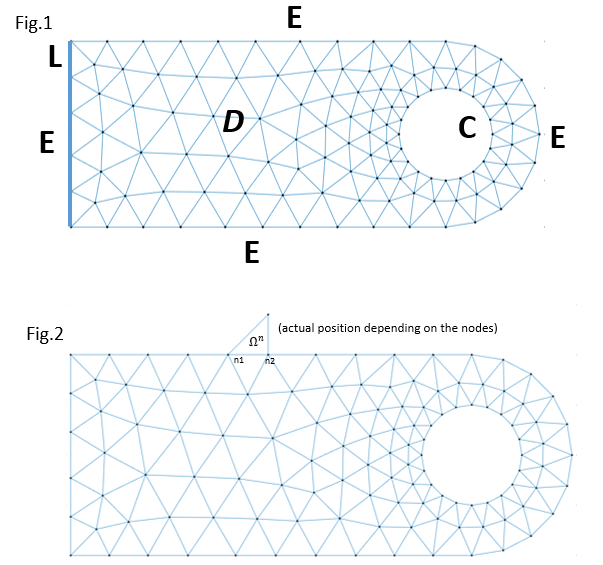

Let $P$ be the point inside the element $\Omega^{82}$, with barycentric coordinates $(0.50, 0.25, 025)$.

### Part (a)

(a) (2 points) Solve the problem when the boundary conditions are: $T = 90$ on $C$, $T=50$ on $L$. The value of $T(P)$ is

**Hint a1:** When no boundary conditions are given, like on $E\setminus L$, it is equivalent to impose the default conditions $q^{k}_{n}\equiv 0$ which is explicitly imposed when you initialize $Q = 0$ in Matlab code.

**Hint a2:** The value of $u(114)$ is `7.1913e+01`. 

- `7.5778e+01`

- `7.6117e+01`

- Leave it empty (no penalty)

- `7.4604e+01 `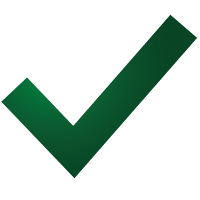

- `7.3212e+01`

#### **Solution**

clearvars
close all

a11 = 1.0;
a12 = 0.0;
a21 = a12;
a22 = a11;
a00 = 0.0;
f   = 0.0;

tempCirc = 90.0;
tempL = 50.0;

baryCoordPointP = [0.50, 0.25, 0.25];
numElemPointP = 82;
numNodHint = 114;

%eval('meshDataHoleS5');
%save 'meshDataHoleS5.mat' nodes elem
load 'meshDataHoleS5.mat' nodes elem

numNod = size(nodes,1);
numElem = size(elem,1);

numbering = 0;
figure;
plotElementsOld(nodes, elem, numbering);
hold on

Pick the nodes at $L$, and at the circle $C$

nodesL = find(nodes(:,1) < 0.01);
nodesCirc = find(sqrt((nodes(:,1)-4).^2 + (nodes(:,2)-1).^2)< 0.501);

Plot the mesh and the selected nodes

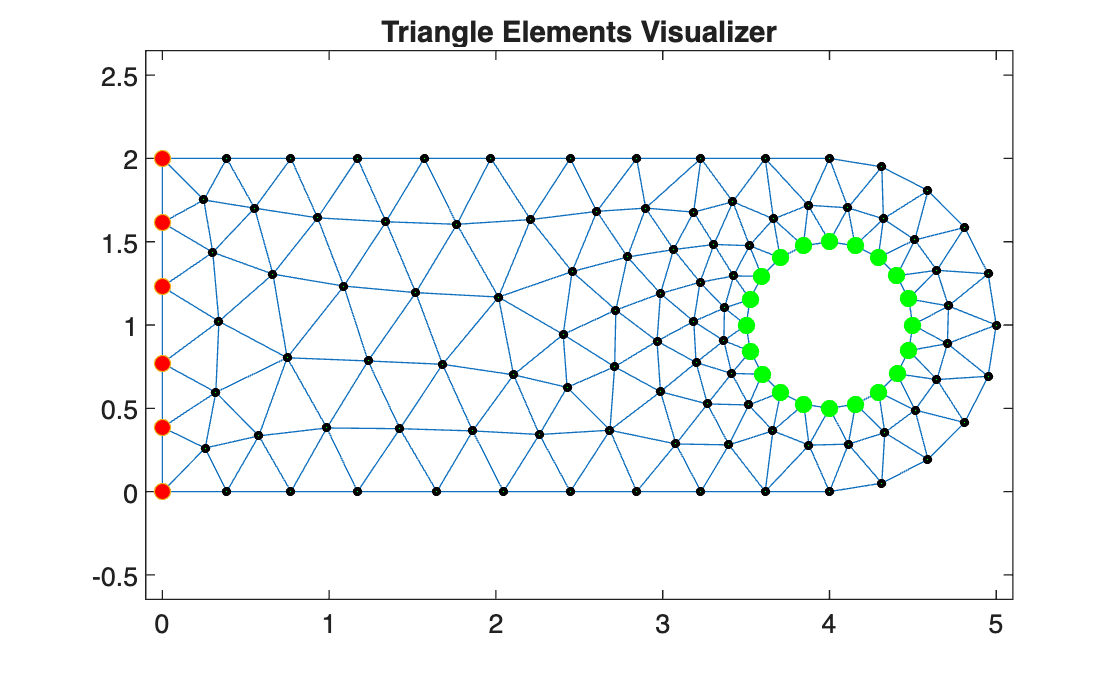

plot(nodes(nodesL,1),nodes(nodesL,2),'o','markerFaceColor','red')
plot(nodes(nodesCirc,1),nodes(nodesCirc,2),'o','markerFaceColor','green','Color','green')
hold off

coeff=[a11,a12,a21,a22,a00,f];
K = zeros(numNod);
F = zeros(numNod,1);
Q = zeros(numNod,1);

for e=1:numElem
    [Ke, Fe] = linearTriangElement(coeff,nodes,elem,e);
    rows =[elem(e,1),elem(e,2),elem(e,3)];
    cols = rows;
    K(rows,cols) = K(rows,cols) + Ke;
    if coeff(6) ~= 0
        F(rows) = F(rows) + Fe;
    end
end
%Kini = K; %save a copy of the stifness matrix for the post porcess

Boundary conditions

fixedNodes = [nodesL',nodesCirc'];
freeNodes = setdiff(1:numNod,fixedNodes);

Natural B.C.: see hint a1

%Natural B.C.: see hint a1

Essential B.C.

%Essential B.C.
u = zeros(numNod,1);
u(nodesL) = tempL;
u(nodesCirc) = tempCirc;

Reduced system

Im = F(freeNodes) + Q(freeNodes) - K(freeNodes,fixedNodes)*u(fixedNodes);
Km = K(freeNodes,freeNodes);

Solution of the reduced system

um = Km\Im;
u(freeNodes) = um;

nodesPointP = elem(numElemPointP,:);
tempPointP = baryCoordPointP * u(nodesPointP);
fprintf(['(a) Approximate temperature at point P: %.4e\n', ...
         '    Hint a2. Approximate temparature at node %d: %.4e\n'], ...
   tempPointP, numNodHint, u(numNodHint));

(a) Approximate temperature at point P: 7.4604e+01
    Hint a2. Approximate temparature at node 114: 7.1913e+01


### Part (b)

(b) (2 points) Consider the same problem with boundary conditions in the whole exterior boundary $E$as in (a), but now the temperature on $C$ is given by $T(x,y) = 25(x-y^{2})$. Then, the value of $T(P)$ is:

*Hint b:* The value $u(114)$ is `5.7331e+01`.

- Leave it empty (no penalty)

- `5.7535e+01`

- `5.6370e+01 `

- `5.5236e+01`

- `5.6743e+01`

#### Solution 

Boundary conditions

%Boundary conditions
%fixedNodes: same as in (a)
%freeNodes: same as in (a)

Natural B.C.: see hint a1

%Natural B.C.: see hint a1

Essential B.C.

%Essential B.C.
u(nodesL) = tempL;
tempBdE = @(x,y) 25*(x - y.^2);
xx = nodes(nodesCirc,1); yy = nodes(nodesCirc,2);
tempCirc = tempBdE(xx,yy);
u(nodesCirc) = tempCirc;

Reduced system

Im = F(freeNodes) + Q(freeNodes) - K(freeNodes,fixedNodes)*u(fixedNodes);
Km = K(freeNodes,freeNodes);

Solution of the the reduced system

um = Km\Im;
u(freeNodes) = um;
tempPointP = baryCoordPointP * u(nodesPointP); 
fprintf(['(b) Approximate temperature at point P: %.4e\n', ...
         '    Hint b. Approximate temparature at node %d: %.4e\n'], ...
   tempPointP, numNodHint, u(numNodHint));

(b) Approximate temperature at point P: 5.6370e+01
    Hint b. Approximate temparature at node 114: 5.7331e+01


### Part (c)

(c) (2 points) Let us define $B = \{(x,y)\in E, x > 3.5\}$. Solve the problem with boundary conditions on $L$ and $C$as in (b), but now, considering on $B$ a convection boundary condition with $\beta = 2$ and $T_{\infty} = 5$. The value $T(P)$ is then:

*Hint c1:* $B$ contains $13$ nodes and the node with the biggest number is $55$.

*Hint c2:* The value of $u(114)$ is `5.3805e+01`.

- `5.2499e+01 ` 

- `5.2622e+01`

- `5.1918e+01`

- Live it empty (no penalty)

- `5.3700e+01` 

#### Solution

Pick the nodes at $L$, at circle $C$, and at $B$

[indNodBd, indElemBd, indLocalEdgBd, edges] = boundaryNodes(nodes, elem);
nodesE = setdiff(indNodBd,nodesCirc);
nodesB = nodesE(nodes(nodesE, 1) > 3.5);

Plot the mesh and the selected nodes

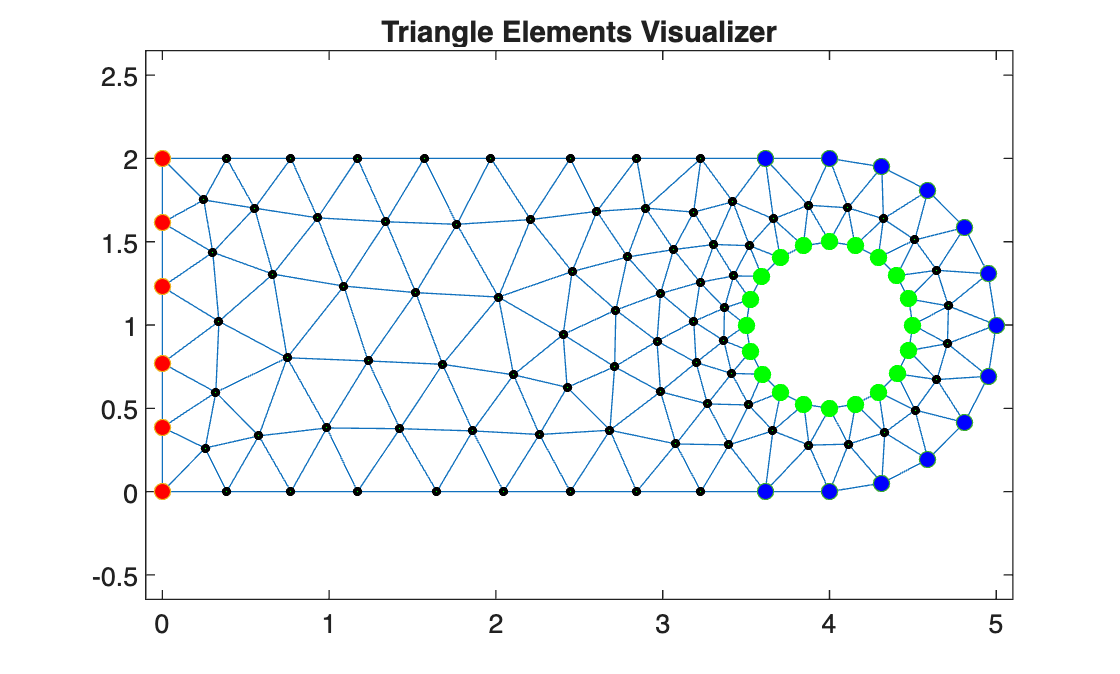

figure;
plotElementsOld(nodes, elem, numbering);
hold on
% Plot boundary nodes and their temperatures
plot(nodes(nodesL,1),nodes(nodesL,2),'o','markerFaceColor','red')
plot(nodes(nodesCirc,1),nodes(nodesCirc,2),'o','markerFaceColor','green','Color','green')
plot(nodes(nodesB,1), nodes(nodesB,2), 'o', 'markerFaceColor', 'blue');
hold off

Boundary Conditions

%Boundary conditions
%fixedNodes: same as in (a) and (b)
%freeNodes: same as in (a) and (b)

Natural B.C.: convection on $B$

%Natural B.C. (convection on B)
beta = 2;
Tinf = 5;
indCV = nodesB';
[K,Q]=applyConvTriang(indCV,beta,Tinf,K,Q,nodes,elem);

Essential B.C.: same as in (b)

%Essential B.C.: same as before

Reduced system

%Reduced system
Im = F(freeNodes) + Q(freeNodes) - K(freeNodes,fixedNodes)*u(fixedNodes);
Km = K(freeNodes,freeNodes);

Solution of the reduced system

um = Km\Im;
u(freeNodes) = um;
tempPointP = baryCoordPointP * u(nodesPointP); 
fprintf(['(c) Approximate temperature at point P: %.4e\n', ...
         '    Hint c1: B contains %d nodes and the largest index is %d\n', ...
         '    Hint c2. Approximate temparature at node %d: %.4e\n'],...
   tempPointP, size(nodesB,1), max(nodesB), numNodHint, u(numNodHint));

(c) Approximate temperature at point P: 5.2499e+01
    Hint c1: B contains 13 nodes and the largest index is 55
    Hint c2. Approximate temparature at node 114: 5.3805e+01


### Part (d)

(d) *(3 points)* By design requirements, we want to enlarge the domain $D$ adding to the mesh a new triangular element. $\Omega^{n}$ (see Figure 2) on the boundary $y = 2$, like an outer spike. Consider $\Omega^{n}$ be an **isosceles right triangle exterior** to $D$ were the nodes $27$ and $26$ are its respective local nodes $1$ and $2$ (i.e. they define $\Gamma^{n}_{1}$).

Therefore, on the initial mesh you have to add a new line both to the elements and nodes tables with the new element and node respectively.

The new domain $\bar{D} = D\cup\Omega^{n}$ shares the same boundaries $C$, $L$ with $D$. Solve the problem in the new domain $\bar{D}$ with the same boundary conditions $T \equiv 50$ on $L$, $T(x,y) = 25(x-y^{2})$ on $C$ (as in (b)) and fixing the temperature of the **new node** to 110. The value of $T(P)$ is:

**Hint d:** The value of $u(114)$ is `6.3545e+01`

- `7.2456e+01`

- `6.9578e+01`

- Leave it empty (no penalty)

- `7.2435e+01`

- `7.0790e+01 `

#### Solution

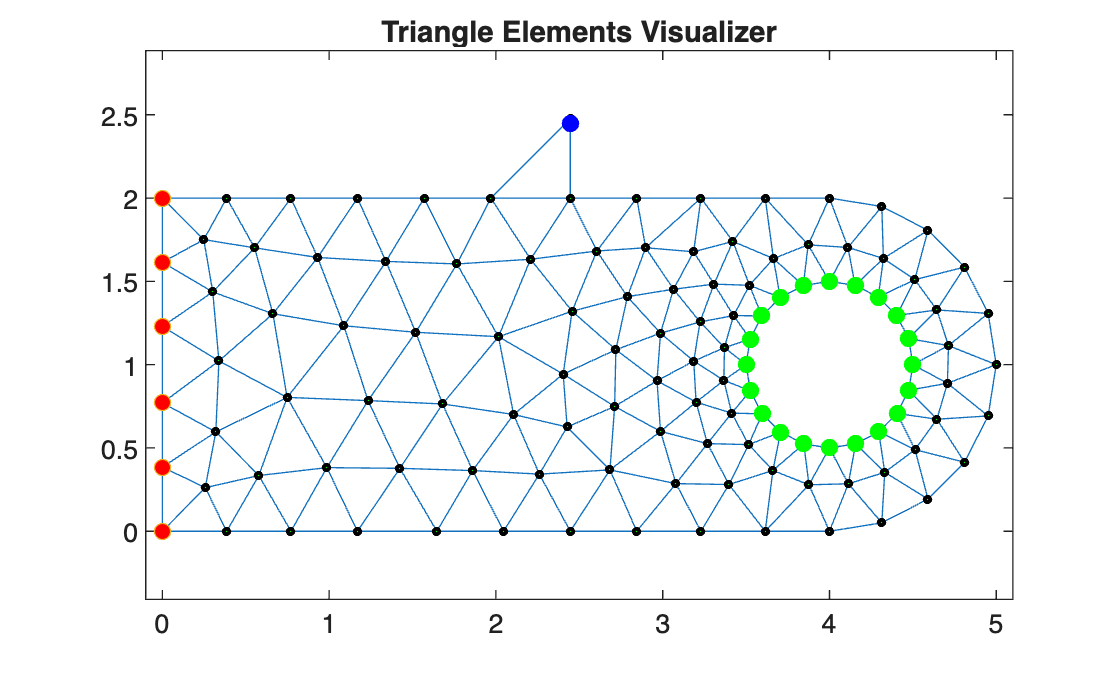

clear K F E u

elem = [elem; 27, 26, numNod+1];
dist = norm(nodes(26)-nodes(27));
nodes = [nodes; nodes(26,1), nodes(26,2)+dist];
numNod = size(nodes,1);
numElem = size(elem,1);

numbering = 0;
plotElementsOld(nodes, elem, numbering);
hold on
plot(nodes(nodesL,1),nodes(nodesL,2),'o','markerFaceColor','red')
plot(nodes(nodesCirc,1),nodes(nodesCirc,2),'o','markerFaceColor','green','Color','green')
plot(nodes(end,1), nodes(end,1),'o','markerFaceColor','blue','Color','blue')
hold off


K = zeros(numNod);
F = zeros(numNod,1);
Q = zeros(numNod,1);

for e = 1:numElem
    [Ke, Fe] = linearTriangElement(coeff, nodes, elem, e);
    rows = [elem(e, 1), elem(e, 2), elem(e, 3)];
    cols = rows;
    K(rows, cols) = K(rows, cols) + Ke;
    if coeff(6) ~= 0
        F(rows) = F(rows) + Fe;
    end
end

%Boundary conditions
u = zeros(numNod,1);
fixedNodes = [fixedNodes, numNod];
freeNodes = setdiff(1:numNod, fixedNodes);

%Natural B.C.: same as in (a) and (b). See hint a1
%Essential B.C.:
u(nodesL) = tempL;
u(nodesCirc) = tempCirc; %same as in (b) and (c)
% Update boundary conditions for the new node
u(end) = 110;

%Reduced system
Im = F(freeNodes) + Q(freeNodes) - K(freeNodes, fixedNodes) * u(fixedNodes);
Km = K(freeNodes, freeNodes);

%Solution of the reduced system
um = Km \ Im;
u(freeNodes) = um;

tempPointP = baryCoordPointP * u(nodesPointP); 

fprintf(['(d) Approximate temperature at point P: %.4e\n',...
         '    Hint d. Approximate temparature at node %d: %.4e\n'],...
        tempPointP, numNodHint, u(numNodHint));

(d) Approximate temperature at point P: 7.0790e+01
    Hint d. Approximate temparature at node 114: 6.3545e+01
